# ECMOR-2022 Paper

gen_q_pos = @(k) (-4)^(k) * (rand()-0.5)^(2*k+1)+0.5;
calc_g = @(u) [1 + 0.5 * u.^2, u];

newton_param = struct(...
    'iters'    , 10,...
    'iters_min', 3,...
    'tol'      , 0,...
    'tol_rel'  , 1e-3,...
    'tol_g'    , 0,...
    'tol_rel_g', 1e-3 ...
    );

ng_param = struct(...
    'iters'    , 10,...
    'iters_min', 3,...
    'tol'      , 0,...
    'tol_rel'  , 1e-3,...
    'tol_g'    , 0,...
    'tol_rel_g', 1e-3 ...
    );

newton_solver = @(x,Res,Jac) newton_gauss(x,Res,Jac,newton_param);

## Theory

### Train / Test samples

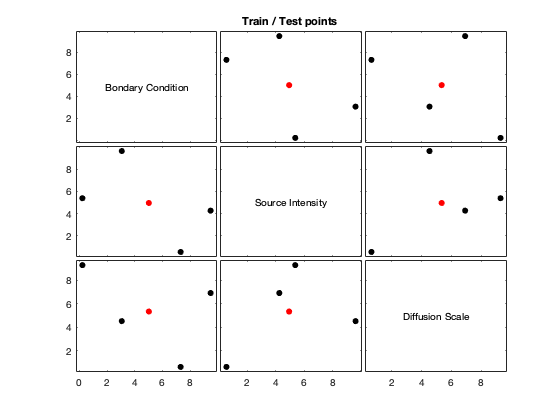

param_names = {'Bondary Condition';'Source Intensity';'Diffusion Scale'};
num_params = length(param_names);
num_train_points = num_params + 1;

train_points = lhsdesign(num_train_points, num_params, 'Smooth','on');

param_scales = [10, 10,  10];
param_biases = [ 0,  0, 0.1];

train_points = train_points .* param_scales + param_biases;

test_point = mean(train_points,1);

all_points = [train_points; test_point];

point_names = split(num2str(1:num_train_points));
point_names{end+1} = 'test point';
gplotmatrix(figure(),all_points,[],point_names,'kkkkr','.',[],'off','variable',param_names);
title('Train / Test points');

### FOM

Stable parameters

Nx = 2000;

param_gen_h = 0.1;
param_gen_clx = 0.1;
initial_condition = genField(Nx, 0, 2, param_gen_h, param_gen_clx);

Variable parameters

q_pos = gen_q_pos(1);
kappa = genField(Nx + 1, 1e-3, 1e-4, param_gen_h, param_gen_clx);

Problem

test_params = gen_params_from(Nx, test_point, q_pos, kappa);
FOM_test = genProblem('FOM',Nx,test_params,initial_condition);
Nt = 100;
FOM_test = solveDif(1, Nt, FOM_test, newton_solver);

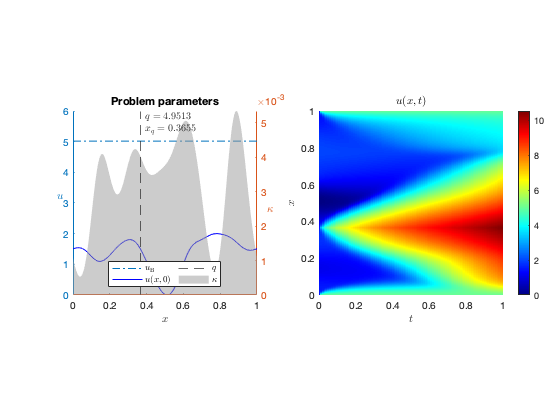

plotSol(figure(),FOM_test);

### ROM

Data

[X_test,W_test,J_test,~] = collectSolData(FOM_test);

#### POD

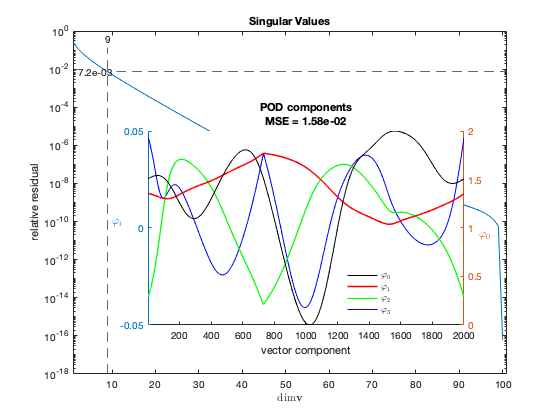

POD_test = PCA(X_test, 1e-2,'init',initial_condition).plotSummary(figure(), 'layout','built-in');

#### ROM-I

ROM_I_test = genProblem('ROM-I', Nx, test_params,initial_condition, POD_test.genEncoder());
ng_solver = @(x,Res,Jac) newton_gauss(x,Res,Jac, ng_param, POD_test.genEncoder().decjac);
ROM_I_test = solveDif(1,Nt,ROM_I_test,ng_solver);
ROM_I_test.X = POD_test.decode(ROM_I_test.X);

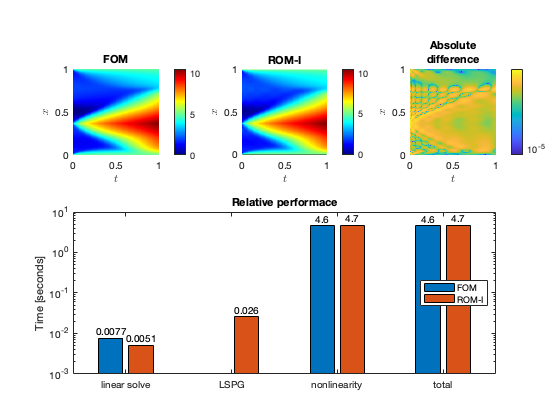

plotComp(figure(),FOM_test,ROM_I_test);

#### Gappy

PODs

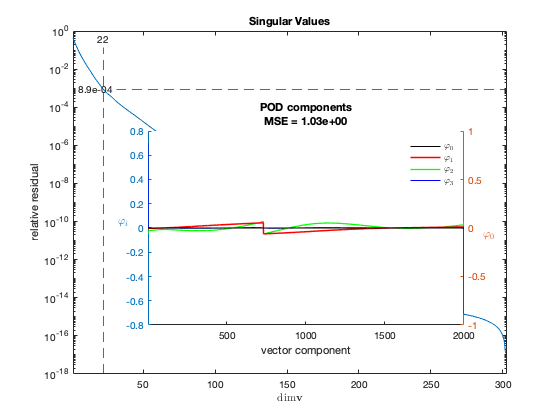

Gappy_W_test = PCA(W_test, 1e-3,'init',zeros(Nx+1,1)).plotSummary(figure());

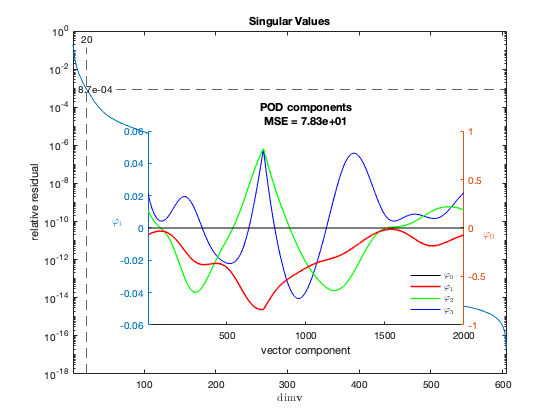

Gappy_J_test = PCA(J_test, 1e-3,'init',zeros(Nx+1,1)).plotSummary(figure());

Greedy mask

gappy_mask_size_w = Gappy_W_test.npc();
gappy_mask_w = Gappy_W_test.calcGreedy(gappy_mask_size_w);

gappy_mask_size_j = Gappy_J_test.npc();
gappy_mask_j = Gappy_J_test.calcGreedy(gappy_mask_size_j);

gappy_mask_empirical = [1,Nx+1,FOM_test.param.q.pos];

gappy_mask_all = [gappy_mask_w,gappy_mask_j,gappy_mask_empirical];
gappy_mask_all = unique(gappy_mask_all);
gappy_mask_all = sort(gappy_mask_all);

POD basis distinction plot

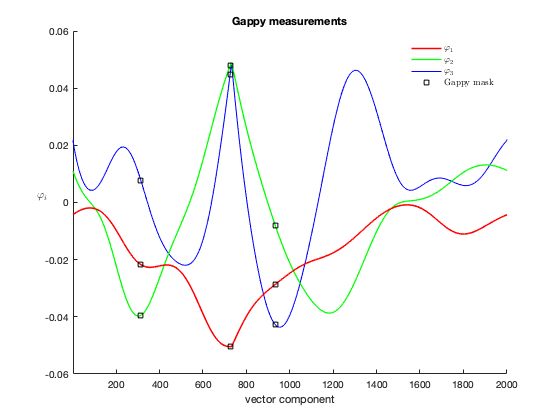

idx = 1:3;
u_mask_w = Gappy_J_test.u(:,idx);

ax = axes(figure);

Nf = size(u_mask_w,1);
xcoord = 1:Nf;
hold(ax,'on');  

yll = ylabel(ax,'$$\varphi_i$$','interpreter','latex');
yll.Rotation = 0;

colors = {'r-','g-','b-'};
lwid = [1.5,1.25,1];

for i = length(idx):-1:1
    pPC{i} = plot(ax,xcoord, u_mask_w(:,i),colors{i},'LineWidth',lwid(i));
end

for i = idx
    gP{i} = scatter(ax,gappy_mask_j(i),u_mask_w(gappy_mask_j(i),idx),'sk');
end

hold(ax,'off');

% legend_entries = [pPC{1} pPC{2} pPC{3} gP{1}];
gappy_legend = gP{1};
legend_entries = [pPC{:}, gappy_legend(1)];

leg1= legend(legend_entries,...
    ['$$\varphi_{',num2str(idx(1)),'}$$'],...
    ['$$\varphi_{',num2str(idx(2)),'}$$'],...
    ['$$\varphi_{',num2str(idx(3)),'}$$'],...
    'Gappy mask',...
    'interpreter','latex');
leg1.Location = 'best';
leg1.Orientation = 'horizontal';
leg1.NumColumns = 1;
leg1.Box = 'off';

ttl = 'Gappy measurements';
title(ax,ttl,'interpreter','tex');
xlim(ax,[1, Nf]);
xlabel(ax,'vector component');
    
xlim(ax,[1, Nf]);
xlabel(ax,'vector component');

Oblique projections

Gappy_W_test = Gappy_W_test.buildGappy(gappy_mask_all);
Gappy_J_test = Gappy_J_test.buildGappy(gappy_mask_all);

#### ROM-II

ROM_II_test = genProblem('ROM-II', Nx, test_params, initial_condition, POD_test.genEncoder(), Gappy_W_test.genNFA(), Gappy_J_test.genNFA());
ng_solver = @(x,Res,Jac) newton_gauss(x,Res,Jac, ng_param, POD_test.genEncoder().decjac);
ROM_II_test = solveDif(1,Nt,ROM_II_test,ng_solver);
ROM_II_test.X = POD_test.decode(ROM_II_test.X);

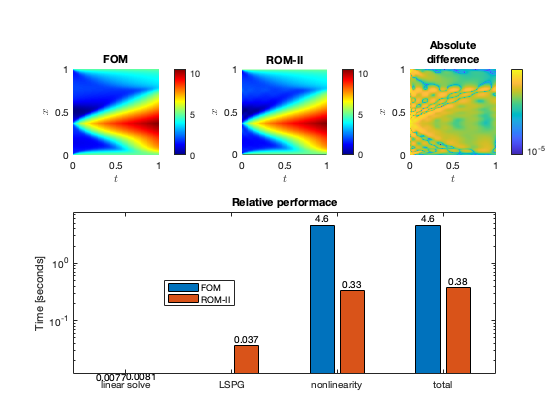

plotComp(figure(),FOM_test,ROM_II_test);

### Generalization Ability

ROM of train data

X_train = [];
W_train = [];
J_train = [];
train_points

train_points =    7.316010910479500   0.543623380724251   0.637863522267126
   9.482420129817315   4.261164509587810   6.922921244621707
   3.062430465045082   9.620385694213789   4.530473237959665
   0.214530446890566   5.380223694215545   9.297441957277622


for i = 1:size(train_points,1)  
    param_i = gen_params_from(Nx,train_points(i,:),q_pos,kappa);
    
    TRAIN = genProblem('TRAIN',Nx,param_i,initial_condition);
    TRAIN = solveDif(1,Nt,TRAIN, newton_solver);
    [X_i,W_i,J_i,~] = collectSolData(TRAIN);
    X_train = [X_train,X_i];
    W_train = [W_train,W_i];
    J_train = [J_train,J_i];
end

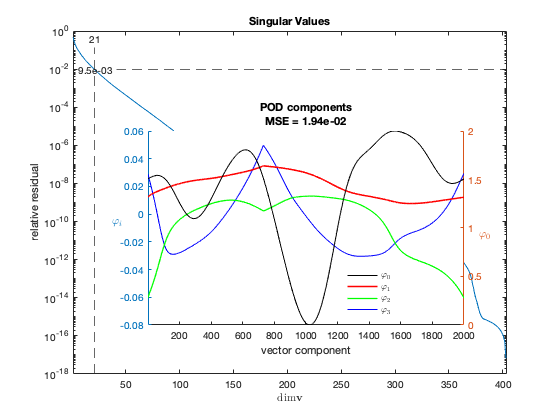

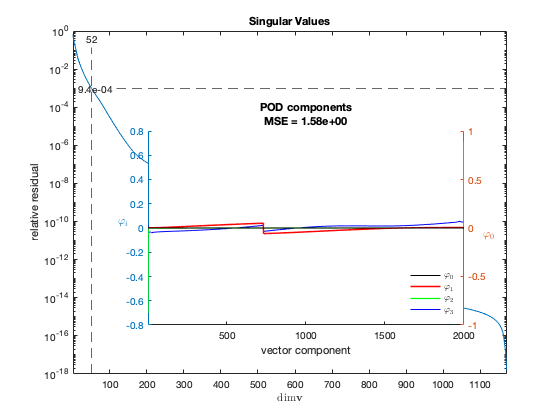

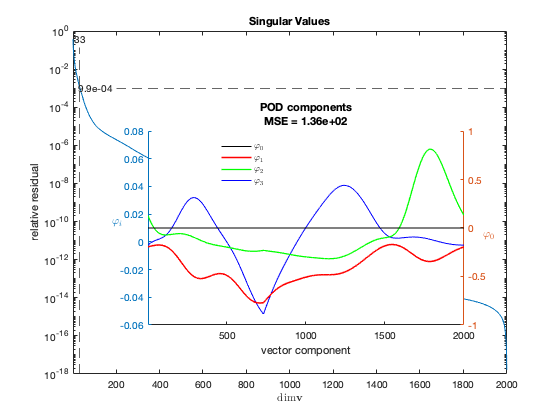

[POD_train, Gappy_W_train, Gappy_J_train] = train_roms(X_train,W_train,J_train, initial_condition,q_pos);

#### High

ROM_II_test = genProblem('ROM-II', Nx, test_params, initial_condition, POD_train.genEncoder(), Gappy_W_train.genNFA(), Gappy_J_train.genNFA());
ng_solver = @(x,Res,Jac) newton_gauss(x,Res,Jac, ng_param, POD_train.genEncoder().decjac);
ROM_II_test = solveDif(1,Nt,ROM_II_test,ng_solver);
ROM_II_test.X = POD_train.decode(ROM_II_test.X);

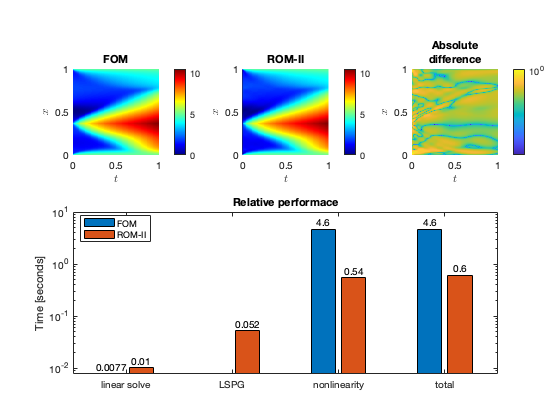

plotComp(figure(),FOM_test,ROM_II_test);

#### Low

- 
$$\Delta x_q$$


d_xq = 0.2;
param_dxq = gen_params_from(Nx,test_point,q_pos*(1+d_xq),kappa);
FOM_dxq = genProblem('FOM-dxq',Nx,param_dxq,initial_condition);

FOM_dxq = solveDif(1, Nt, FOM_dxq, newton_solver);

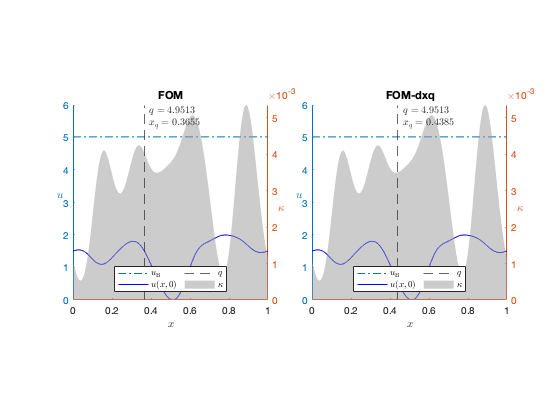

comp_problems(FOM_test,FOM_dxq);

ROM_II_dxq = genProblem('ROM-II-dxq', Nx, param_dxq, initial_condition, POD_train.genEncoder(), Gappy_W_train.genNFA(), Gappy_J_train.genNFA());
ng_solver = @(x,Res,Jac) newton_gauss(x,Res,Jac, ng_param, POD_train.genEncoder().decjac);
ROM_II_dxq = solveDif(1,Nt,ROM_II_dxq,ng_solver);
ROM_II_dxq.X = POD_train.decode(ROM_II_dxq.X);

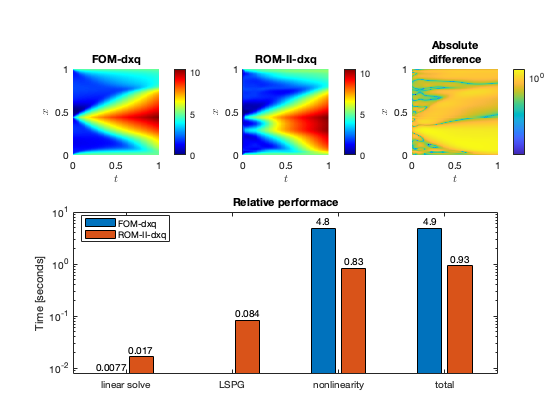

plotComp(figure(),FOM_dxq,ROM_II_dxq);

- 
$$\Delta \kappa(x)$$


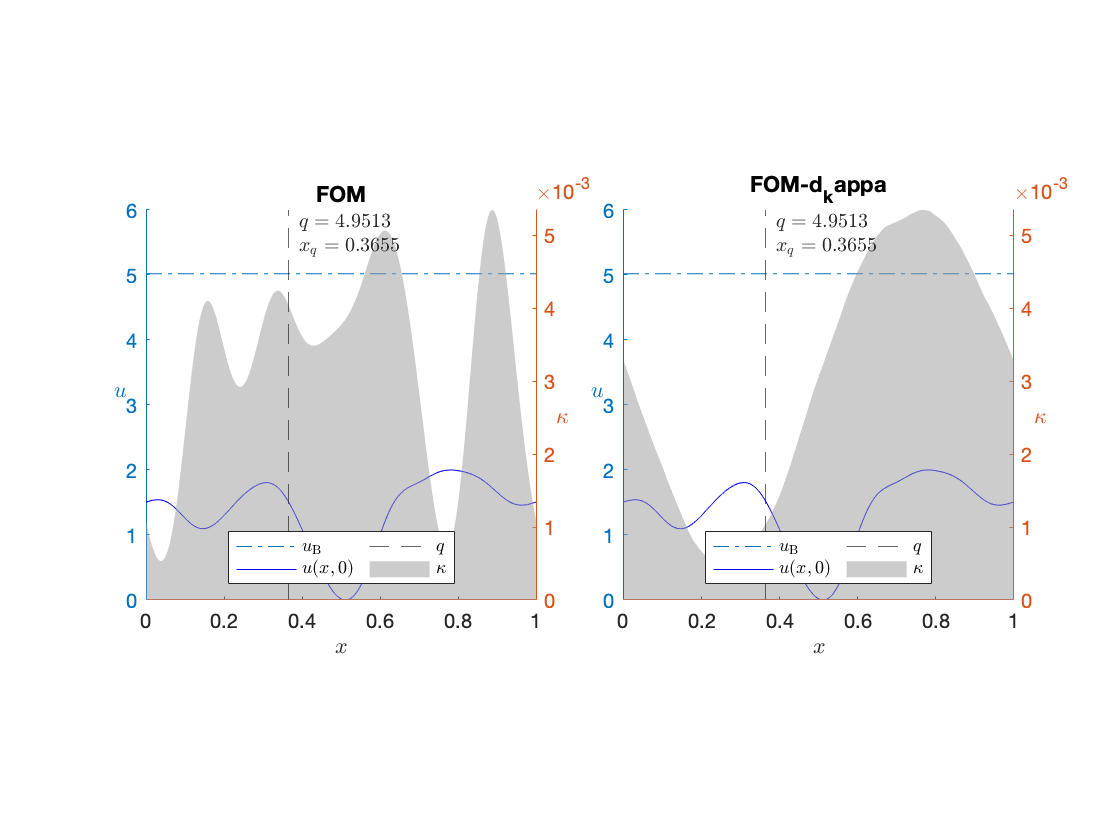

d_kappa = genField(Nx + 1, 1e-3, 1e-4, param_gen_h, param_gen_clx*5);
param_d_kappa = gen_params_from(Nx,test_point,q_pos,d_kappa);
FOM_d_kappa = genProblem('FOM-d_kappa',Nx,param_d_kappa,initial_condition);
comp_problems(FOM_test,FOM_d_kappa);

FOM_d_kappa = solveDif(1, Nt, FOM_d_kappa, newton_solver);

ROM_I_d_kappa = genProblem('ROM-I-dkappa', Nx, param_d_kappa, initial_condition, POD_train.genEncoder());
ng_solver = @(x,Res,Jac) newton_gauss(x,Res,Jac, ng_param, POD_train.genEncoder().decjac);
ROM_I_d_kappa = solveDif(1,Nt,ROM_I_d_kappa,ng_solver);
ROM_I_d_kappa.X = POD_train.decode(ROM_I_d_kappa.X);

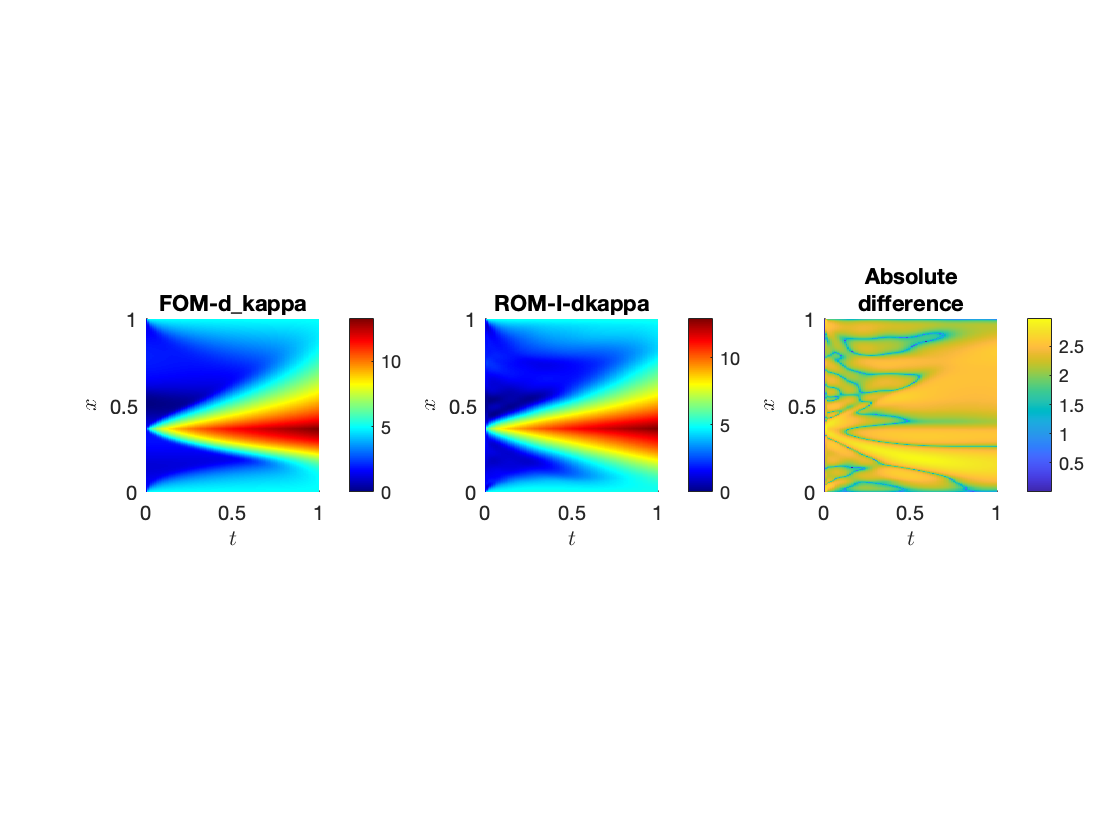

plotComp(figure(),FOM_d_kappa,ROM_I_d_kappa, true);

## Method

### Subdomain scheme

text

### Zero-order approach

### Domain-Wise for x_q

### Domain-Wise for kappa

### Domain-Wise for combined

## Functions

function [out] = gen_params_from(Nx, point, q_pos, kappa)
bc_val = point(1);
boundary_condition = repmat(bc_val,1,2);
BC = genBC(1,boundary_condition);

kappa_scale = point(3);
medium = kappa * kappa_scale;
D.val = medium; 
D.model = @(u) [1 + 0.5 * u.^2, u];

source_intensity = point(2);
Q.pos = round(Nx*q_pos); 
Q.val = sparse(Q.pos,1,source_intensity, Nx, 1);

out = genParam(D,BC,Q);
end

function [POD, Gappy_W, Gappy_J] = train_roms(X_data, W_data, J_data, initial_condition, q_pos)
% PODs
POD     = PCA(X_data, 1e-2, 'init', initial_condition).plotSummary(figure());
Nw = size(W_data,1);
Gappy_W = PCA(W_data, 1e-3, 'init', zeros(Nw,1)    ).plotSummary(figure());
Gappy_J = PCA(J_data, 1e-3, 'init', zeros(Nw,1)    ).plotSummary(figure());

% Gappy mask
gappy_mask_size_w = Gappy_W.npc();
gappy_mask_size_j = Gappy_J.npc();

gappy_mask_w = Gappy_W.calcGreedy(gappy_mask_size_w);
gappy_mask_j = Gappy_J.calcGreedy(gappy_mask_size_j);

gappy_mask_empirical = [1,Nw, round((Nw-(-1:1))*q_pos)];

gappy_mask_all = [gappy_mask_w,gappy_mask_j,gappy_mask_empirical];
gappy_mask_all = unique(gappy_mask_all);
gappy_mask_all = sort(gappy_mask_all);

% oblique projections
Gappy_W = Gappy_W.buildGappy(gappy_mask_all);
Gappy_J = Gappy_J.buildGappy(gappy_mask_all);
end

function [] = comp_problems(problem_1,problem_2)
tiledlayout(figure,1,2,'TileSpacing','tight');

sp1 = nexttile;
plotProblem(sp1,problem_1);
title(sp1,problem_1.name);

sp2 = nexttile;
plotProblem(sp2,problem_2);
title(sp2,problem_2.name);
end